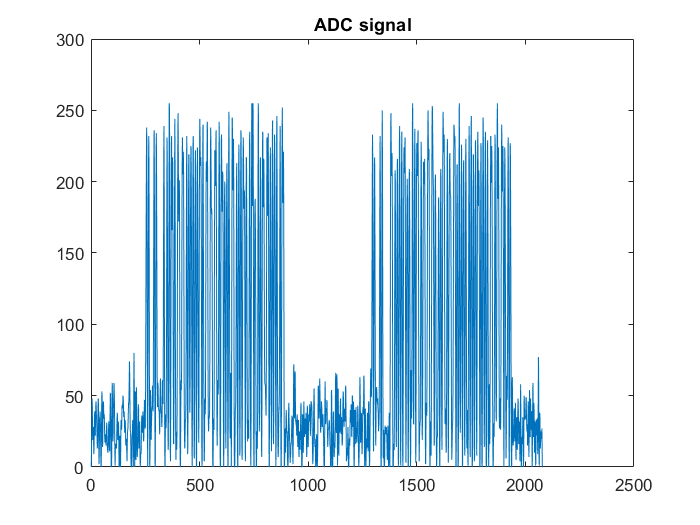

load("TestVoltage.mat")
load("ConvolutionArray.mat")
convIndex = 1;
konvSignalas = GenerateConv(all_adc, convTypes(convIndex).convPreambule);
plot(all_adc)
title("ADC signal")

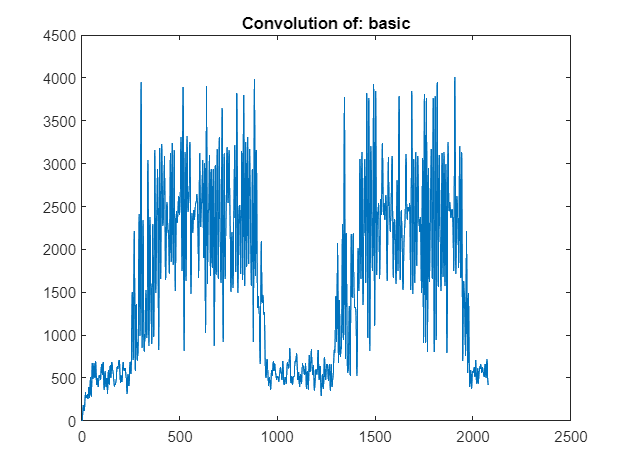

plot(konvSignalas)
title(sprintf("Convolution of: %s", convTypes(convIndex).name))

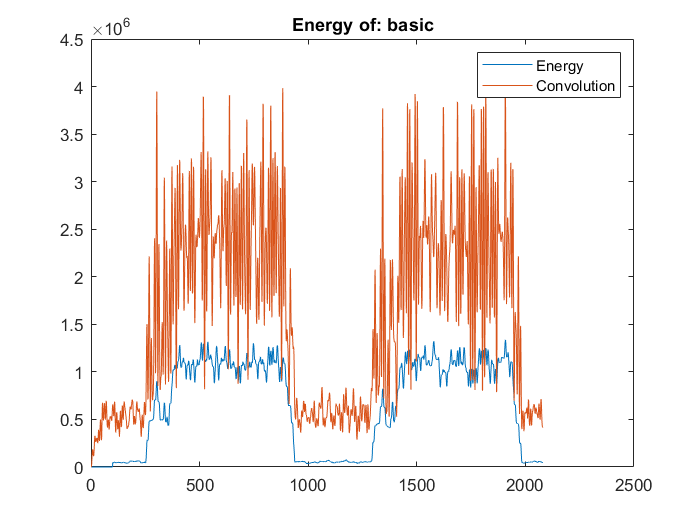

windowLength = length(convTypes(convIndex).convPreambule);
currentEnergy = zeros(1, length(all_adc));
currentApproximation = zeros(1, length(all_adc));
for i = 100:length(currentEnergy)
    energyMaxPoint = i;
    energyMinPoint = i - windowLength;
    currentEnergy(i) = sum(abs(all_adc(energyMinPoint : energyMaxPoint) .* all_adc(energyMinPoint : energyMaxPoint)));
end
plot(currentEnergy, 'DisplayName', "Energy")
hold on
plot(konvSignalas*1000, 'DisplayName', "Convolution")
hold off
legend
title(sprintf("Energy of: %s", convTypes(convIndex).name))

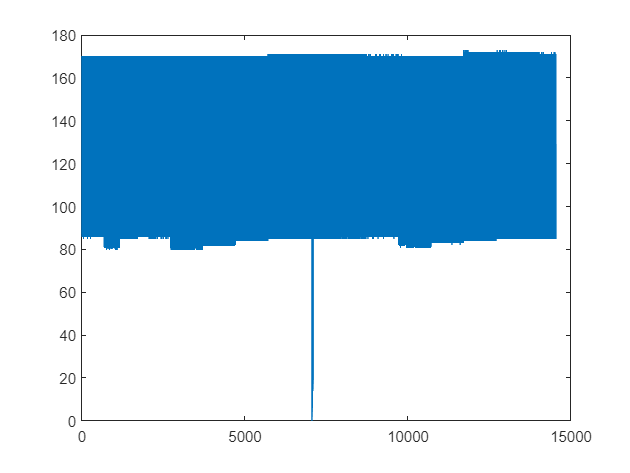

%Skaitymas is windows forms programos sugeneruoto failo
msfile = fopen('received_data.txt','r');

formatSpec = ['%d'];

msdata = fscanf(msfile,formatSpec, [1 inf]);

plot(msdata)